%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%% Diagnostics test analysis %%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% Gabriele Pozzato (gpozzato@stanford.edu) %%%%%% Date: 2022/01 %%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% In case of help, feel free to contact the author %%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear all
close all
clc

warning off

%% User input
% Cell selection for capacity test, HPPC, and EIS
% --------------------------
% sel_cell -> col_cell_label
% --------------------------
% 1        -> W3
% 2        -> W4
% 3        -> W5
% 4        -> W7
% 5        -> W8
% 6        -> W9
% 7        -> W10
% 8        -> G1
% 9        -> V4
% 10       -> V5
% --------------------------
sel_cell = 2;                                                              

% SOC selection for EIS only
% --------------------
% sel_SOC -> soc_level
% --------------------
% 1       -> 20% 
% 2       -> 50% 
% 3       -> 80% 
% --------------------
sel_SOC = 2;

%% General
legend_str = {'Diag. \#1','Diag. \#2','Diag. \#3','Diag. \#4','Diag. \#5',...
              'Diag. \#6','Diag. \#7','Diag. \#8','Diag. \#9','Diag. \#10',...
              'Diag. \#11','Diag. \#12','Diag. \#13','Diag. \#14','Diag. \#15'};
nominal_capacity = 4.85;                                                    % [Ah]
base_path = "/home/ccanodom/data/EV_battery/Complete/"

base_path = "/home/ccanodom/data/EV_battery/Complete/"

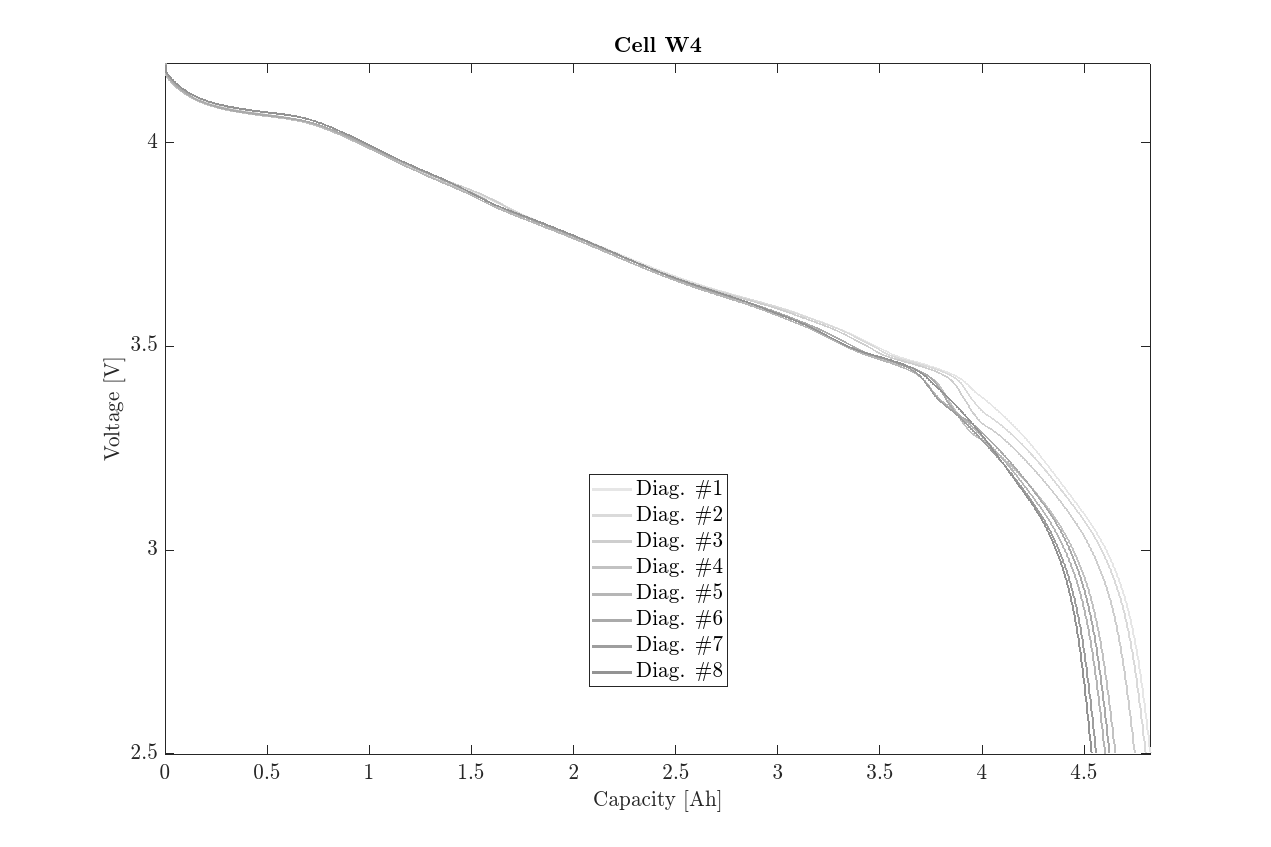

%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CAPACITY TEST %%%%%%%%%%%%%%%%%%%%%%%%%%%
load(base_path + "capacity_test.mat")

% Plot capacity test
rgb_num = linspace(0.25,0.9,length(legend_str));
my_colormap = flip((rgb_num.*ones(length(rgb_num),3)')');

figure('Position',[600 100 1500 1000]); hold on; box on
for i = 1:size(time,1)
    if isnan(vcell{i,sel_cell})
        break
    end
    plot(cap{i,sel_cell},vcell{i,sel_cell},'linewidth',2,'color',my_colormap(i,:))
end
xlabel('Capacity [Ah]'); ylabel('Voltage [V]'); legend(legend_str,'location','best')
xlim([-inf inf]); ylim([-inf inf]); title(['\textbf{Cell ' col_cell_label{sel_cell} '}'])
set(findall(gcf,'-property','FontSize'),'FontSize',16)
set(findall(gcf,'-property','interpreter'),'interpreter','latex')
set(findall(gcf,'-property','ticklabelinterpreter'),'ticklabelinterpreter','latex')

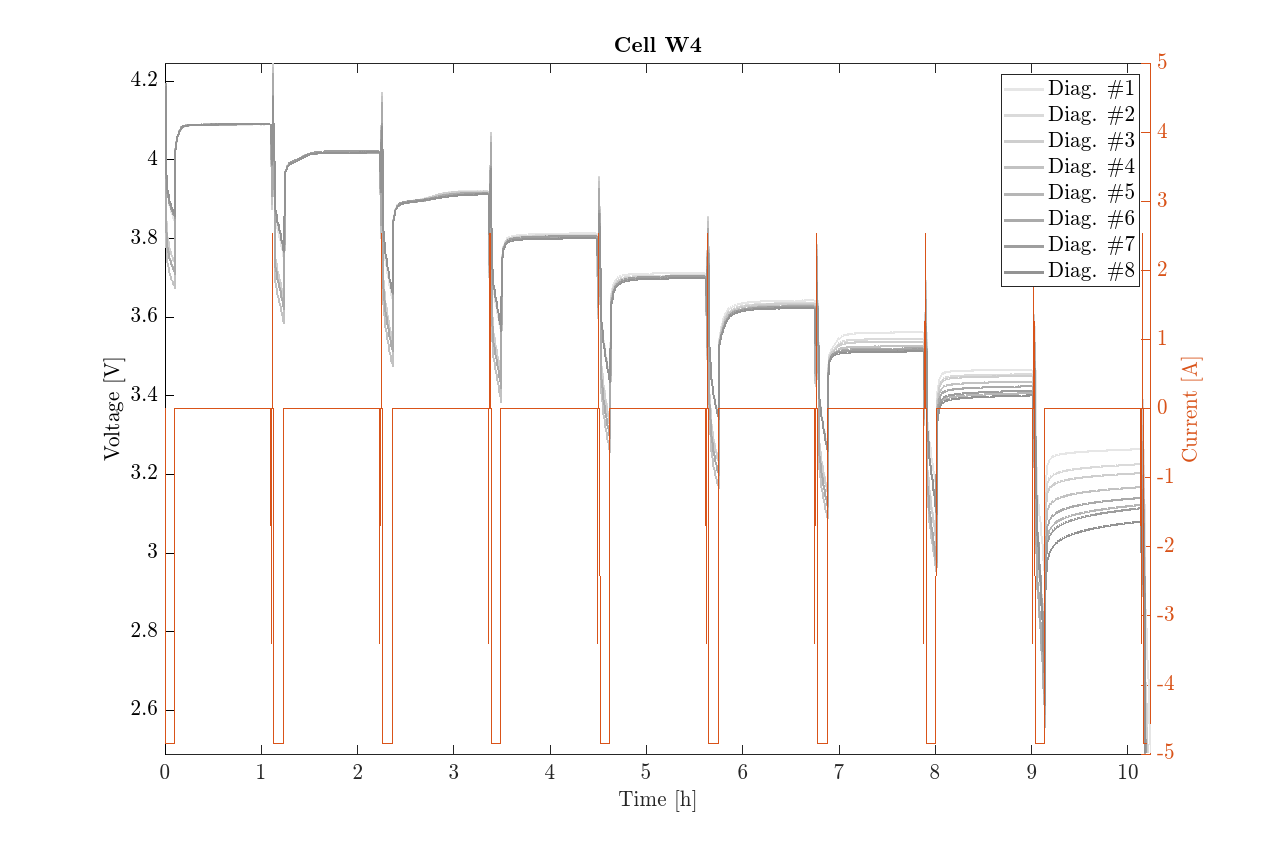



%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%% HPPC TEST %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clearvars -except base_path legend_str nominal_capacity sel_cell sel_SOC my_colormap; 
load(base_path + 'HPPC_test.mat')

        % Plot HPPC

figure('Position',[600 100 1500 1000]);  hold on; box on; yyaxis left; 
for i = 1:size(time,1)
    if ~isnan(vcell{i,sel_cell})
        plot(time{i,sel_cell}/3600,vcell{i,sel_cell},'-','linewidth',2,'color',my_colormap(i,:),'DisplayName',legend_str{i})
    end
end
ylabel('Voltage [V]','Color','k'); ylim([-inf inf]); set(gca,'YColor','k'); legend show
yyaxis right; plot(time{2,sel_cell}/3600,curr{2,sel_cell},'-','linewidth',1,'HandleVisibility','off') 
ylabel('Current [A]'); ylim([-5 5]); title(['\textbf{Cell ' col_cell_label{sel_cell} '}'])
xlabel('Time [h]'); xlim([-inf inf]); 
set(findall(gcf,'-property','FontSize'),'FontSize',16)
set(findall(gcf,'-property','interpreter'),'interpreter','latex')
set(findall(gcf,'-property','ticklabelinterpreter'),'ticklabelinterpreter','latex')

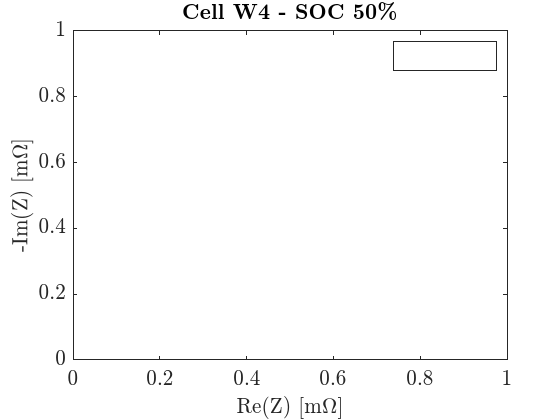


%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%% EIS TEST %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clearvars -except base_path legend_str nominal_capacity sel_cell sel_SOC my_colormap; 
load(base_path + 'EIS_test.mat')

% EIS @SOC
figure; hold on; box on; 
for i = 1:length(row_diag_number)
    if ~isnan(re_z{i,sel_cell})
        plot(1000*re_z{i,sel_cell}(:,sel_SOC),-1000*im_z{i,sel_cell}(:,sel_SOC),...
             '-*','linewidth',1.5,'color',my_colormap(i,:),'DisplayName',legend_str{i})
    end
end
title(['\textbf{Cell ' col_cell_label{sel_cell} ' - SOC ' num2str(soc_level(sel_SOC)) '\%}'])
ylabel('-Im(Z) [m$\Omega$]'); xlabel('Re(Z) [m$\Omega$]'); xlim([-inf inf]); ylim([0 inf]*1000)
legend show
set(findall(gcf,'-property','FontSize'),'FontSize',16)
set(findall(gcf,'-property','interpreter'),'interpreter','latex')
set(findall(gcf,'-property','ticklabelinterpreter'),'ticklabelinterpreter','latex')